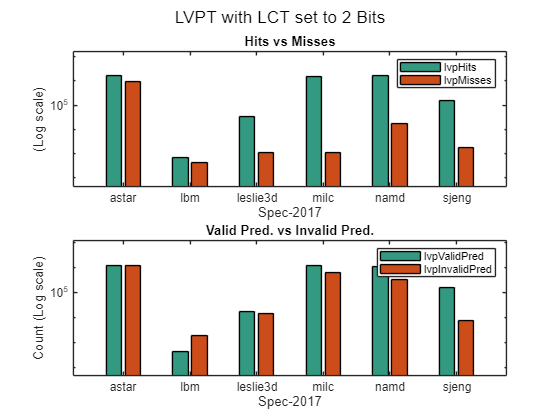

clear;
clc;
close all;

% Read the data from the CSV file, with the first row as the header
data = readtable('rational_lvp_lct_2-3.csv', 'PreserveVariableNames', true);

% Extract the benchmark names (the first column)
benchmarks = data{:, 1};  % Access the first column using numeric indexing

% Create a figure with two subplots arranged vertically
figure;

% Define the color pair for the bars (using RGB triplets)
barColors = [ [0.8 0.3 0.1]; [0.2 0.6 0.5] ];  % Teal and orange

% First subplot: lvpHits and lvpMisses
subplot(2, 1, 1);  % 2 rows, 1 column, first subplot
bar(categorical(benchmarks), [data.lvpHits, data.lvpMisses]);
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
legend('lvpHits', 'lvpMisses');
title('Hits vs Misses');
xlabel('Spec-2017');
ylabel('(Log scale)');

% Change bar colors
ax = gca;
ax.Children(1).FaceColor = barColors(1,:); 
ax.Children(2).FaceColor = barColors(2,:);

% Add offset to the top of the y-axis
ylim([min([data.lvpHits; data.lvpMisses])/10, max([data.lvpHits; data.lvpMisses])*10]);

% Second subplot: lvpValidPred and lvpInvalidPred
subplot(2, 1, 2);  % 2 rows, 1 column, second subplot
bar(categorical(benchmarks), [data.lvpValidPred, data.lvpInvalidPred]);
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
legend('lvpValidPred', 'lvpInvalidPred');
title('Valid Pred. vs Invalid Pred.');
xlabel('Spec-2017');
ylabel('Count (Log scale)');

% Change bar colors (use the same color pair)
ax = gca;
ax.Children(1).FaceColor = barColors(1,:);
ax.Children(2).FaceColor = barColors(2,:); 

% Add offset to the top of the y-axis
ylim([min([data.lvpValidPred; data.lvpInvalidPred])/10, max([data.lvpValidPred; data.lvpInvalidPred])*10]);

% Adjust the layout
sgtitle('LVPT with LCT set to 2 Bits')